## Turbine

Starting from the beginning, we define the turbine as a Pelton wheel type, which is often used in micro hydro applications. The wikipedia page very clearly states a formula for the force on the blade. Using the radius of the turbine, we get a torque. 

For this, we need the velocity of the water hitting the wheel. This can be found from the assumed nozzle jet outlet diameter and the volumetric flow rate. The volumetric flow rate will eventually vary with time, as it is a parameter of the river. For now, we set it to a constant. 

The only state variable in this initial model is the angular velocity of the turbine, modelled as the inertia of a disc. 

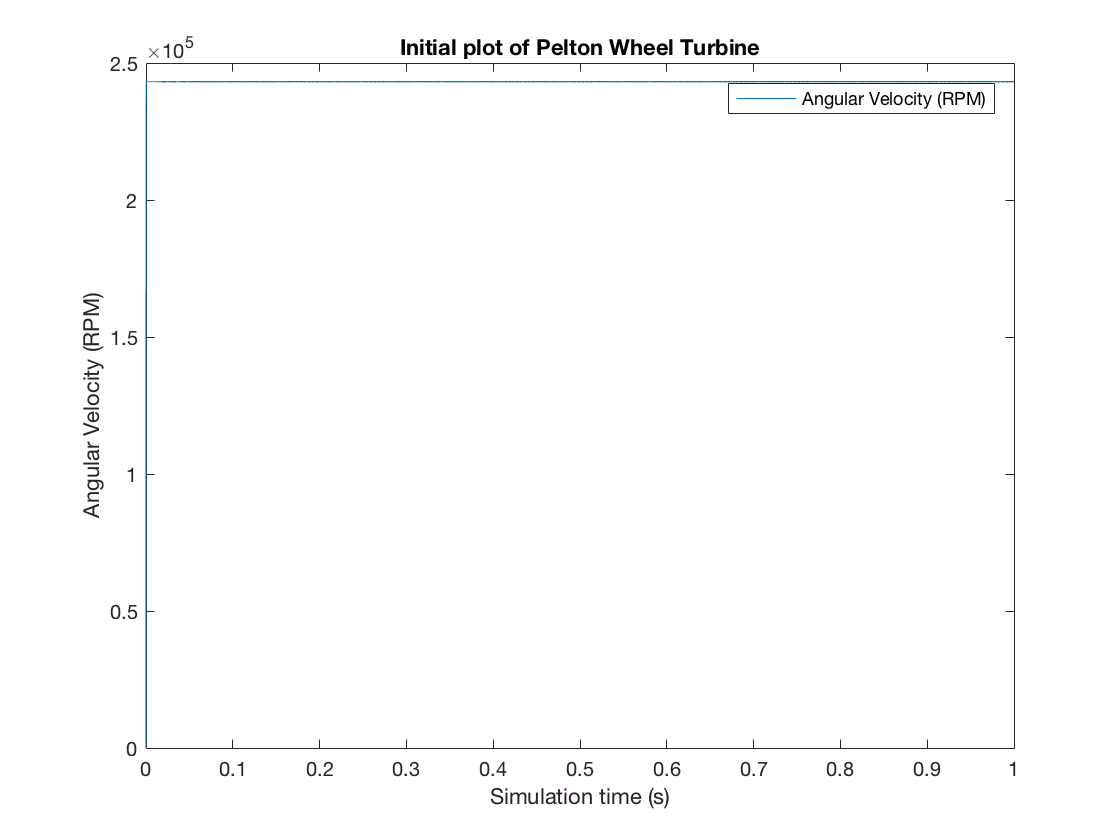

y0 = [0]; % initial angular velocity = 0
[t,y] = ode45(@turbine, [0:0.01:1], y0);
y = y / (2*pi) * 60; % convert to RPM
plot(t,y)
title('Initial plot of Pelton Wheel Turbine')
legend('Angular Velocity (RPM)')
xlabel('Simulation time (s)')
ylabel('Angular Velocity (RPM)')

function xprime = turbine(t,y)
    Q = 2; % this is the input, assume constant flow for now
    mass_turb = 5;
    radius_turb = 0.1;
    a_jet = 0.005^2 * pi;
    J = 0.5 * mass_turb * radius_turb^2; % approximate as a disc

    xprime = (radius_turb/J) * (-2 * 1000 * Q * y(1) + (( 2 * 1000 * Q^2)/a_jet));
end

The results of this simulation show an extremely fast ramp up, and then a relatively constant velocity. This is what should be expected, since there are no loads on the turbing and no consideration for viscous damping. 

**Improvements**: add viscous damping, add more complex nozzle (page 58, textbook)

## Add Viscous Damping

y0 = [0]; % initial angular velocity = 0
[t,y] = ode45(@turbine2, [0:0.01:1], y0);
y = y / (2*pi) * 60; % convert to RPM
figure
plot(t,y)
title('Initial plot of Pelton Wheel Turbine')
legend('Angular Velocity (RPM)')
xlabel('Simulation time (s)')
ylabel('Angular Velocity (RPM)')

function xprime = turbine2(t,y)
    Q = 1; % this is the input, assume constant flow for now
    mass_turb = 5;
    radius_turb = 0.1;
    a_jet = 0.005^2 * pi;
    J = 0.5 * mass_turb * radius_turb^2; % approximate as a disc
    b_turb = 5000;

    xprime = (radius_turb/J) * (-2 * 1000 * Q * y(1) + (( 2 * 1000 * Q^2)/a_jet)) - y(1)*b_turb/J;
end

## Modify Turbine Equation, add Motor Inertia and Friction

Using the equations for force on the wheel from here: [https://issuu.com/ijsrd/docs/ijsrdv3i100075,](https://issuu.com/ijsrd/docs/ijsrdv3i100075,) the eqution for jet velocity was modified. Now, it is dependent on the pressure head, not the input flow rate.

Torque equation: *T* = *F*(*D*/2) = *ρQD*(*V*i − *u*) 

    - (Vi = jet velocity, u = wheel velocity)

    - [https://en.wikipedia.org/wiki/Pelton_wheel](https://en.wikipedia.org/wiki/Pelton_wheel)

Also, the friction coefficients were reduced. 

## Determine K

Values for the various constants in the system must be determined for simulation. Ideally, they will be calculated directly from reasonable assumptions about the system. 

Equation for torsional spring: T = -k * theta

Equation for deflection of shaft under torsion: theta = (Length * Torque)/(GJ)

    Where J = polar moment of inertia and G = shear modulus 

Therefore, k = -JG/L

y0 = [0,0,0]; % initial angular velocity = 0
[t,y] = ode45(@turbine3, [0 10], y0);
power = y(:,2) .* y(:,3);
y = y / (2*pi) * 60; % convert to RPM
figure
plot(t,y)
hold on
plot(t, power)
title('Initial plot of Pelton Wheel Turbine')
legend('Turbine RPM','Generator RPM','Shaft Torque (N*m)', 'Shaft Power (W)')
xlabel('Simulation time (s)')
ylabel('Angular Velocity (RPM)')

function xprime = turbine3(t,y)
Q = 5/1000; % (5 lps) this is the input, assume constant flow for now
head = 50;
mass_turb = 10;
radius_turb = 0.15;
a_jet = 0.002^2 * pi;
J_turb = 0.5 * mass_turb * radius_turb^2; % approximate as a disc
b_turb = 0.2;
J_gen = 0.005; % less than the turbine
jet_factor = 0.97; % to account for losses and such

% Shaft parameters
G = 80E9; % stainless steel
d = 1/100; % 1cm
l = 0.1; % 10cm
% calculate_k = @(G, d, l) -(((pi * d^4)/32)*G)/l;
K = -785.3982;%calculate_k(G,d,l);
b_gen = 0.35;

xprime(1,1) = (2000 * Q * radius_turb / J_turb)*(jet_factor * sqrt(2*9.8*head) - y(1)*radius_turb) - y(1)*b_turb/J_turb - y(3)/J_turb;
xprime(2,1) = (y(3) - y(2)*b_gen)/J_gen;
xprime(3,1) = K * (-y(1) + y(2)); % spring
end

This results in a net output power of about 1200 Watts. Compared with the maximum theoretical power of P = rho * g * head * Q = 2450 W, an efficiency of about 50% is found. 

## Generator

The equivalent circuit of the generator is the same as a motor operated in reverse. Vemf is the generated voltage. The generator constant (emf constant for a motor) is found from a linear fit of the test data from an example alternator, the DC-540 from here: [http://www.windbluepower.com/Permanent_Magnet_Alternator_Wind_Blue_Low_Wind_p/dc-540.htm](http://www.windbluepower.com/Permanent_Magnet_Alternator_Wind_Blue_Low_Wind_p/dc-540.htm)

One other required parameter is the inductance of the coil in the generator. Since the DC-540 is a rewound automotive alternator, we take the inductance to be 0.115H from this paper: [http://cdn.intechopen.com/pdfs/38166/InTech-Power_electronic_solutions_to_improve_the_performance_of_lundell_automotive_alternators.pdf](http://cdn.intechopen.com/pdfs/38166/InTech-Power_electronic_solutions_to_improve_the_performance_of_lundell_automotive_alternators.pdf) (pg.183)

The stator resistance is also added to the model, taken to be 0.27 Ω from the discussion here:[http://forums.pelicanparts.com/porsche-911-technical-forum/199928-alternator-stator-coil-resistance.html](http://forums.pelicanparts.com/porsche-911-technical-forum/199928-alternator-stator-coil-resistance.html) 